## Gabriel Werpel Fernandes

## June 2024

## Load Data

% Close all figures and clear variables
clc;
close all;
clearvars;

%Process EEG Data
data = processAllEEGData();

Data for file A1_Full_Block.bdf processed successfully
Data for file A3_Full_Block.bdf processed successfully
Data for file A4_Full_Block.bdf processed successfully
Data for file A6_Alpha.bdf processed successfully
Data for file A8_Alpha.bdf processed successfully
Data for file A9_Alpha.bdf processed successfully
Data for file C12_Alpha.bdf processed successfully
Data for file C13_Alpha.bdf processed successfully
Data for file C15_Alpha.bdf processed successfully
Data for file C1_Alpha.bdf processed successfully


## Plot Time-Series

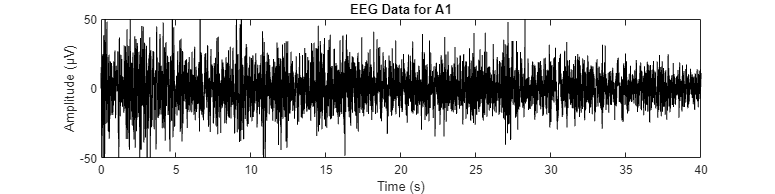

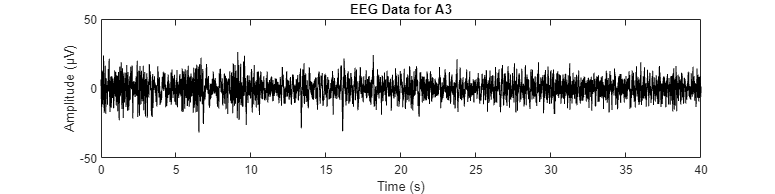

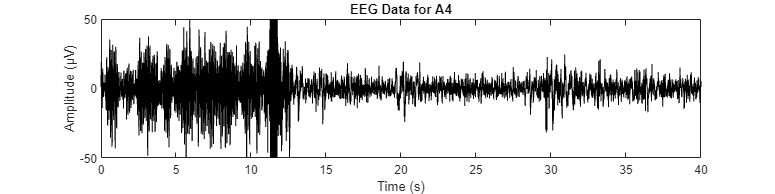

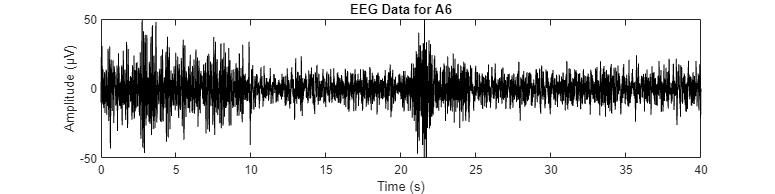

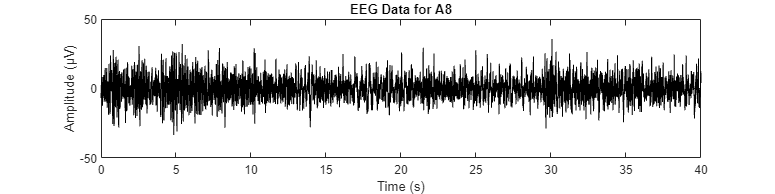

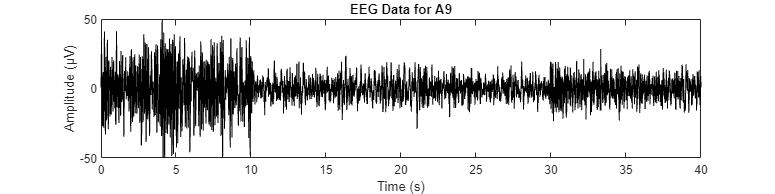

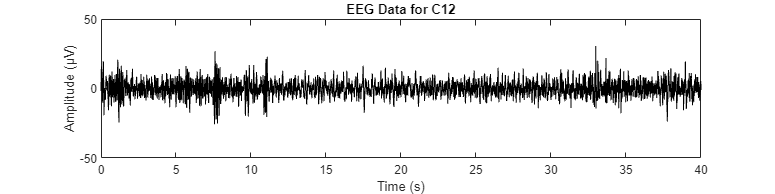

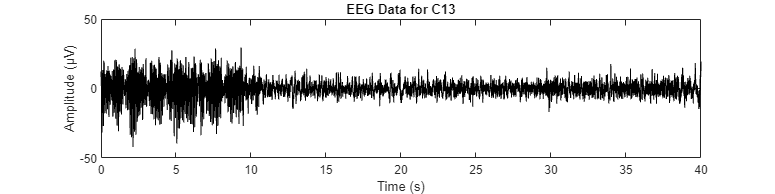

% Plot all EEG data
plotAllEEGData(data);

## Segment Data

% Segment the EEG data
segmentedData = segmentEEGDataNew(data);

## Time-Domain Analysis

### Statistical Measures: Mean, Variance, Std. Deviation, Skewness and Kurtosis

% Calculate and display the extended statistics for all keys and sections
extendedStatisticsResults = calculateExtendedStatisticsForAllSections(segmentedData);

      Key             Section             DataType      Mean     Variance    StandardDeviation    Skewness    Kurtosis
    _______    ______________________    __________    ______    ________    _________________    ________    ________

    {'A1' }    {'EC'                }    {'Normal'}    -0.158     320.02           17.889           0.012       3.441 
    {'A1' }    {'EO'                }    {'Normal'}     0.051        150           12.247          -0.039       3.837 
    {'A1' }    {'DEC'               }    {'Normal'}     -0.04      108.7           10.426           0.292       3.873 
    {'A1' }    {'NDEC'              }    {'Normal'}     0.042     78.528            8.862           0.031        3.09 
    {'A1' }  

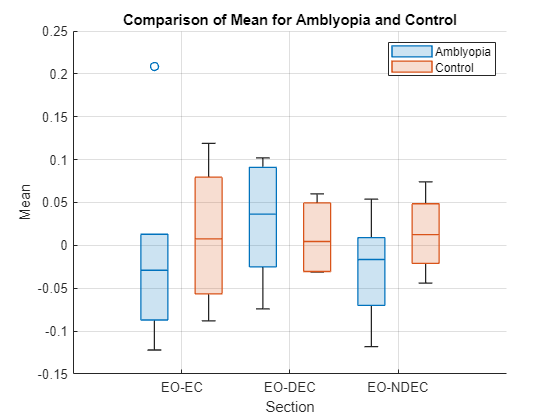

% Load the data
data = readtable('TableA.1.1.csv');

% Call the function for each metric
plotBoxChart(data, 'Mean', 'Mean');

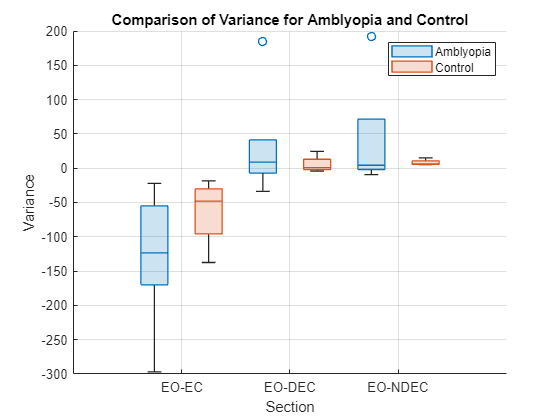

plotBoxChart(data, 'Variance', 'Variance');

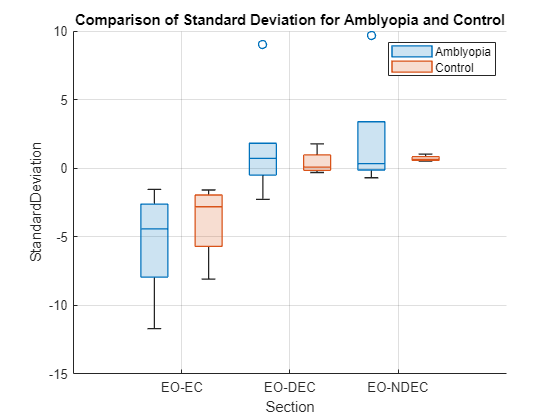

plotBoxChart(data, 'StandardDeviation', 'Standard Deviation');

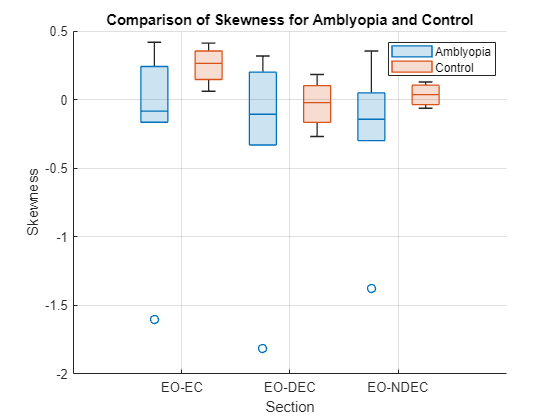

plotBoxChart(data, 'Skewness', 'Skewness');

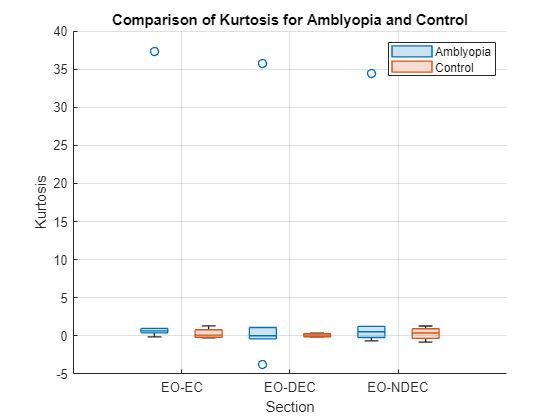

plotBoxChart(data, 'Kurtosis', 'Kurtosis');

% Define the sections of interest
sections = {'EC', 'EO', 'DEC', 'NDEC'};
measures = {'Mean', 'Variance', 'StandardDeviation', 'Skewness', 'Kurtosis'};

% Initialize structures to hold the data for each group, section, and measure
amblyopiaData = struct();
controlData = struct();

% Loop through each section and measure to separate the data
for i = 1:length(sections)
    section = sections{i};
    for j = 1:length(measures)
        measure = measures{j};
        % Extract data for Amblyopia group in each section for each measure
        amblyopiaData.(section).(measure) = data.(measure)(strcmp(data.Section, section) & startsWith(data.Key, 'A'));
        % Extract data for Control group in each section for each measure
        controlData.(section).(measure) = data.(measure)(strcmp(data.Section, section) & startsWith(data.Key, 'C'));
    end
end


% Specify the hypothesized mean value for the one-sample t-test
mu = 0; % Change this value as needed

% Initialize results structure and table
results = struct();
resultsTable = {};

% Loop through each section and measure
for i = 1:length(sections)
    section = sections{i};
    for j = 1:length(measures)
        measure = measures{j};
        fprintf('Analyzing section: %s, measure: %s\n', section, measure);
        
        % One-sample t-test for Amblyopia group
        [hA, pA_oneSample] = ttest(amblyopiaData.(section).(measure), mu);
        % One-sample t-test for Control group
        [hC, pC_oneSample] = ttest(controlData.(section).(measure), mu);
        
        % Store one-sample t-test results
        results.(section).(measure).pValueOneSampleAmblyopia = pA_oneSample;
        results.(section).(measure).pValueOneSampleControl = pC_oneSample;
        
        % Print results for one-sample t-tests
        fprintf('Section %s, Measure %s - One-sample t-test p-value for Amblyopia: %g\n', section, measure, pA_oneSample);
        fprintf('Section %s, Measure %s - One-sample t-test p-value for Control: %g\n', section, measure, pC_oneSample);
        
        % Proceed with two-sample comparison only if both groups show significant results in one-sample t-tests
        if pA_oneSample < 0.05 && pC_oneSample < 0.05
            % Normality test using Kolmogorov-Smirnov test
            [~, pA_norm] = kstest((amblyopiaData.(section).(measure) - mean(amblyopiaData.(section).(measure))) / std(amblyopiaData.(section).(measure)));
            [~, pC_norm] = kstest((controlData.(section).(measure) - mean(controlData.(section).(measure))) / std(controlData.(section).(measure)));
        
            % Variance test
            [~, p_var] = vartest2(amblyopiaData.(section).(measure), controlData.(section).(measure));
        
            % Choose and perform statistical test based on normality and variance results
            if pA_norm > 0.05 && pC_norm > 0.05 && p_var > 0.05
                [~, p_test] = ttest2(amblyopiaData.(section).(measure), controlData.(section).(measure), 'Vartype', 'equal');
            elseif pA_norm > 0.05 && pC_norm > 0.05
                [~, p_test] = ttest2(amblyopiaData.(section).(measure), controlData.(section).(measure), 'Vartype', 'unequal');
            else
                [p_test, ~] = ranksum(amblyopiaData.(section).(measure), controlData.(section).(measure));
            end
        
            % Store results
            results.(section).(measure).pValueNormalityAmblyopia = pA_norm;
            results.(section).(measure).pValueNormalityControl = pC_norm;
            results.(section).(measure).pValueVariance = p_var;
            results.(section).(measure).pValueTest = p_test;
            
            % Output results for this section and measure
            fprintf('Section %s, Measure %s - P-value for two-sample test: %g\n', section, measure, p_test);
            
            % Add results to table
            resultsTable = [resultsTable; {section, measure, pA_oneSample, pC_oneSample, pA_norm, pC_norm, p_var, p_test}];
        else
            % Skip two-sample test if one-sample tests are not significant
            fprintf('Section %s, Measure %s - Skipping two-sample test due to non-significant one-sample test results.\n', section, measure);
            results.(section).(measure).pValueTest = NaN; % Indicate that the test was not performed
            
            % Add results to table with NaN for the two-sample test
            resultsTable = [resultsTable; {section, measure, pA_oneSample, pC_oneSample, NaN, NaN, NaN, NaN}];
        end
    end
end

Analyzing section: EC, measure: Mean


Section EC, Measure Mean - One-sample t-test p-value for Amblyopia: 0.918221


Section EC, Measure Mean - One-sample t-test p-value for Control: 0.81034


Section EC, Measure Mean - Skipping two-sample test due to non-significant one-sample test results.


Analyzing section: EC, measure: Variance


Section EC, Measure Variance - One-sample t-test p-value for Amblyopia: 0.00831784


Section EC, Measure Variance - One-sample t-test p-value for Control: 0.00747784


Section EC, Measure Variance - P-value for two-sample test: 0.073394


Analyzing section: EC, measure: StandardDeviation


Section EC, Measure StandardDeviation - One-sample t-test p-value for Amblyopia: 0.000790377


Section EC, Measure StandardDeviation - One-sample t-test p-value for Control: 0.000423251


Section EC, Measure StandardDeviation - P-value for two-sample test: 0.117272


Analyzing section: EC, measure: Skewness


Section EC, Measure Skewness - One-sample t-test p-value for Amblyopia: 0.24352


Section EC, Measure Skewness - One-sample t-test p-value for Control: 0.0988711


Section EC, Measure Skewness - Skipping two-sample test due to non-significant one-sample test results.


Analyzing section: EC, measure: Kurtosis


Section EC, Measure Kurtosis - One-sample t-test p-value for Amblyopia: 3.90106e-07


Section EC, Measure Kurtosis - One-sample t-test p-value for Control: 9.03451e-05


Section EC, Measure Kurtosis - P-value for two-sample test: 0.0377789


Analyzing section: EO, measure: Mean


Section EO, Measure Mean - One-sample t-test p-value for Amblyopia: 0.845236


Section EO, Measure Mean - One-sample t-test p-value for Control: 0.859107


Section EO, Measure Mean - Skipping two-sample test due to non-significant one-sample test results.


Analyzing section: EO, measure: Variance


Section EO, Measure Variance - One-sample t-test p-value for Amblyopia: 0.0282961


Section EO, Measure Variance - One-sample t-test p-value for Control: 0.00193813


Section EO, Measure Variance - P-value for two-sample test: 0.235889


Analyzing section: EO, measure: StandardDeviation


Section EO, Measure StandardDeviation - One-sample t-test p-value for Amblyopia: 0.00113527


Section EO, Measure StandardDeviation - One-sample t-test p-value for Control: 0.000106456


Section EO, Measure StandardDeviation - P-value for two-sample test: 0.281836


Analyzing section: EO, measure: Skewness


Section EO, Measure Skewness - One-sample t-test p-value for Amblyopia: 0.339633


Section EO, Measure Skewness - One-sample t-test p-value for Control: 0.31723


Section EO, Measure Skewness - Skipping two-sample test due to non-significant one-sample test results.


Analyzing section: EO, measure: Kurtosis


Section EO, Measure Kurtosis - One-sample t-test p-value for Amblyopia: 0.140503


Section EO, Measure Kurtosis - One-sample t-test p-value for Control: 1.40671e-05


Section EO, Measure Kurtosis - Skipping two-sample test due to non-significant one-sample test results.


Analyzing section: DEC, measure: Mean


Section DEC, Measure Mean - One-sample t-test p-value for Amblyopia: 0.0392938


Section DEC, Measure Mean - One-sample t-test p-value for Control: 0.293322


Section DEC, Measure Mean - Skipping two-sample test due to non-significant one-sample test results.


Analyzing section: DEC, measure: Variance


Section DEC, Measure Variance - One-sample t-test p-value for Amblyopia: 0.00524439


Section DEC, Measure Variance - One-sample t-test p-value for Control: 0.0192571


Section DEC, Measure Variance - P-value for two-sample test: 0.576051


Analyzing section: DEC, measure: StandardDeviation


Section DEC, Measure StandardDeviation - One-sample t-test p-value for Amblyopia: 0.000157227


Section DEC, Measure StandardDeviation - One-sample t-test p-value for Control: 0.000775621


Section DEC, Measure StandardDeviation - P-value for two-sample test: 0.552094


Analyzing section: DEC, measure: Skewness


Section DEC, Measure Skewness - One-sample t-test p-value for Amblyopia: 0.943911


Section DEC, Measure Skewness - One-sample t-test p-value for Control: 0.735038


Section DEC, Measure Skewness - Skipping two-sample test due to non-significant one-sample test results.


Analyzing section: DEC, measure: Kurtosis


Section DEC, Measure Kurtosis - One-sample t-test p-value for Amblyopia: 0.000125344


Section DEC, Measure Kurtosis - One-sample t-test p-value for Control: 8.40854e-05


Section DEC, Measure Kurtosis - P-value for two-sample test: 0.577992


Analyzing section: NDEC, measure: Mean


Section NDEC, Measure Mean - One-sample t-test p-value for Amblyopia: 0.0263929


Section NDEC, Measure Mean - One-sample t-test p-value for Control: 0.48809


Section NDEC, Measure Mean - Skipping two-sample test due to non-significant one-sample test results.


Analyzing section: NDEC, measure: Variance


Section NDEC, Measure Variance - One-sample t-test p-value for Amblyopia: 0.00106751


Section NDEC, Measure Variance - One-sample t-test p-value for Control: 0.00532221


Section NDEC, Measure Variance - P-value for two-sample test: 0.612485


Analyzing section: NDEC, measure: StandardDeviation


Section NDEC, Measure StandardDeviation - One-sample t-test p-value for Amblyopia: 2.58176e-05


Section NDEC, Measure StandardDeviation - One-sample t-test p-value for Control: 0.000301588


Section NDEC, Measure StandardDeviation - P-value for two-sample test: 0.584598


Analyzing section: NDEC, measure: Skewness


Section NDEC, Measure Skewness - One-sample t-test p-value for Amblyopia: 0.937444


Section NDEC, Measure Skewness - One-sample t-test p-value for Control: 0.0921138


Section NDEC, Measure Skewness - Skipping two-sample test due to non-significant one-sample test results.


Analyzing section: NDEC, measure: Kurtosis


Section NDEC, Measure Kurtosis - One-sample t-test p-value for Amblyopia: 5.08486e-05


Section NDEC, Measure Kurtosis - One-sample t-test p-value for Control: 7.1091e-06


Section NDEC, Measure Kurtosis - P-value for two-sample test: 0.662922



% Convert resultsTable to a formal table with column names
resultsTable = cell2table(resultsTable, ...
    'VariableNames', {'Section', 'Measure', 'pValueOneSampleAmblyopia', 'pValueOneSampleControl', 'pValueNormalityAmblyopia', 'pValueNormalityControl', 'pValueVariance', 'pValueTest'});

% Display the table
disp(resultsTable);

    Section            Measure           pValueOneSampleAmblyopia    pValueOneSampleControl    pValueNormalityAmblyopia    pValueNormalityControl    pValueVariance    pValueTest
    ________    _____________________    ________________________    ______________________    ________________________    ______________________    ______________    __________

    {'EC'  }    {'Mean'             }              0.91822                    0.81034                      NaN                        NaN                    NaN             NaN 
    {'EC'  }    {'Variance'         }            0.0083178                  0.0074778                   0.8129                    0.98565               0.036705        0.073394 
    {'EC'  }   


% Save the table to a CSV file
writetable(resultsTable, 'StatisticalResults.csv');



% Initialize results structure and table
results = struct();
resultsTable = {};

% Loop through each section and measure
for i = 1:length(sections)
    section = sections{i};
    for j = 1:length(measures)
        measure = measures{j};
        fprintf('Analyzing section: %s, measure: %s\n', section, measure);

        % Normality test using Kolmogorov-Smirnov test
        [~, pA_norm] = kstest((amblyopiaData.(section).(measure) - mean(amblyopiaData.(section).(measure))) / std(amblyopiaData.(section).(measure)));
        [~, pC_norm] = kstest((controlData.(section).(measure) - mean(controlData.(section).(measure))) / std(controlData.(section).(measure)));

        % Variance test
        [~, p_var] = vartest2(amblyopiaData.(section).(measure), controlData.(section).(measure));

        % Choose and perform statistical test based on normality and variance results
        if pA_norm > 0.05 && pC_norm > 0.05 && p_var > 0.05
            [~, p_test] = ttest2(amblyopiaData.(section).(measure), controlData.(section).(measure), 'Vartype', 'equal');
        elseif pA_norm > 0.05 && pC_norm > 0.05
            [~, p_test] = ttest2(amblyopiaData.(section).(measure), controlData.(section).(measure), 'Vartype', 'unequal');
        else
            [p_test, ~] = ranksum(amblyopiaData.(section).(measure), controlData.(section).(measure));
        end

        % Store results
        results.(section).(measure).pValueNormalityAmblyopia = pA_norm;
        results.(section).(measure).pValueNormalityControl = pC_norm;
        results.(section).(measure).pValueVariance = p_var;
        results.(section).(measure).pValueTest = p_test;

        % Output results for this section and measure
        fprintf('Section %s, Measure %s - P-value for two-sample test: %g\n', section, measure, p_test);

        % Add results to table
        resultsTable = [resultsTable; {section, measure, pA_norm, pC_norm, p_var, p_test}];
    end
end

Analyzing section: EC, measure: Mean


Section EC, Measure Mean - P-value for two-sample test: 0.820937


Analyzing section: EC, measure: Variance


Section EC, Measure Variance - P-value for two-sample test: 0.073394


Analyzing section: EC, measure: StandardDeviation


Section EC, Measure StandardDeviation - P-value for two-sample test: 0.117272


Analyzing section: EC, measure: Skewness


Section EC, Measure Skewness - P-value for two-sample test: 0.415613


Analyzing section: EC, measure: Kurtosis


Section EC, Measure Kurtosis - P-value for two-sample test: 0.0377789


Analyzing section: EO, measure: Mean


Section EO, Measure Mean - P-value for two-sample test: 0.998452


Analyzing section: EO, measure: Variance


Section EO, Measure Variance - P-value for two-sample test: 0.235889


Analyzing section: EO, measure: StandardDeviation


Section EO, Measure StandardDeviation - P-value for two-sample test: 0.281836


Analyzing section: EO, measure: Skewness


Section EO, Measure Skewness - P-value for two-sample test: 0.270913


Analyzing section: EO, measure: Kurtosis


Section EO, Measure Kurtosis - P-value for two-sample test: 1


Analyzing section: DEC, measure: Mean


Section DEC, Measure Mean - P-value for two-sample test: 0.689902


Analyzing section: DEC, measure: Variance


Section DEC, Measure Variance - P-value for two-sample test: 0.576051


Analyzing section: DEC, measure: StandardDeviation


Section DEC, Measure StandardDeviation - P-value for two-sample test: 0.552094


Analyzing section: DEC, measure: Skewness


Section DEC, Measure Skewness - P-value for two-sample test: 0.824767


Analyzing section: DEC, measure: Kurtosis


Section DEC, Measure Kurtosis - P-value for two-sample test: 0.577992


Analyzing section: NDEC, measure: Mean


Section NDEC, Measure Mean - P-value for two-sample test: 0.602481


Analyzing section: NDEC, measure: Variance


Section NDEC, Measure Variance - P-value for two-sample test: 0.612485


Analyzing section: NDEC, measure: StandardDeviation


Section NDEC, Measure StandardDeviation - P-value for two-sample test: 0.584598


Analyzing section: NDEC, measure: Skewness


Section NDEC, Measure Skewness - P-value for two-sample test: 0.400391


Analyzing section: NDEC, measure: Kurtosis


Section NDEC, Measure Kurtosis - P-value for two-sample test: 0.662922



% Convert resultsTable to a formal table with column names
resultsTable = cell2table(resultsTable, ...
    'VariableNames', {'Section', 'Measure', 'pValueNormalityAmblyopia', 'pValueNormalityControl', 'pValueVariance', 'pValueTest'});

% Display the table
disp(resultsTable);

    Section            Measure           pValueNormalityAmblyopia    pValueNormalityControl    pValueVariance    pValueTest
    ________    _____________________    ________________________    ______________________    ______________    __________

    {'EC'  }    {'Mean'             }            0.92361                    0.94879                 0.45959        0.82094 
    {'EC'  }    {'Variance'         }             0.8129                    0.98565                0.036705       0.073394 
    {'EC'  }    {'StandardDeviation'}            0.82763                    0.98541                 0.12133        0.11727 
    {'EC'  }    {'Skewness'         }            0.81622                    0.66416                 0.63513        0.41561 
    {'EC'  }    {'Kurtosis'         }            0.


% Save the table to a CSV file
writetable(resultsTable, 'StatisticalResults.csv');



### Statistical comparison between groups.

% Compare various metrics between A* and C* groups for all sections and data types
compareMetricsByGroupsAndDataTypes(extendedStatisticsResults);

### Peak Analysis


% Perform peak analysis with custom parameters
peakData = performPeakAnalysis(segmentedData, 'MinPeakProminence', [0.5, 1, 1.5], 'MinPeakDistance', [50, 100, 150], 'NPeaks', [5, 10, 15]);


% Run the statistical analysis
analyzePeakData(peakData);


function peakData = performPeakAnalysis(segmentedData, varargin)
    % Parse input arguments
    p = inputParser;
    addParameter(p, 'MinPeakHeight', []);
    addParameter(p, 'Threshold', []);
    addParameter(p, 'MinPeakProminence', [0.5, 1, 1.5]);
    addParameter(p, 'MinPeakDistance', [50, 100, 150]);
    addParameter(p, 'NPeaks', [5, 10, 15]);
    addParameter(p, 'WidthReference', 'halfprom');
    addParameter(p, 'SortStr', 'none'); % Can be 'ascend', 'descend', or 'none'
    addParameter(p, 'Annotate', false);
    parse(p, varargin{:});

    % Get parsed input values
    minPeakHeight = p.Results.MinPeakHeight;
    threshold = p.Results.Threshold;
    minPeakProminenceValues = p.Results.MinPeakProminence;
    minPeakDistanceValues = p.Results.MinPeakDistance;
    nPeaksValues = p.Results.NPeaks;
    widthReference = p.Results.WidthReference;
    sortStr = p.Results.SortStr;
    annotate = p.Results.Annotate;

    % Initialize structure to store peak data
    peakData = struct;

    % Get all the keys for the groups (e.g., A1, A2, C1, etc.)
    groups = fieldnames(segmentedData);

    % Conditions to analyze
    conditions = {'EC', 'EO', 'DEC', 'NDEC'};

    % Iterate through each combination of parameter values
    for pIdx = 1:numel(minPeakProminenceValues)
        for dIdx = 1:numel(minPeakDistanceValues)
            for nIdx = 1:numel(nPeaksValues)
                minPeakProminence = minPeakProminenceValues(pIdx);
                minPeakDistance = minPeakDistanceValues(dIdx);
                nPeaks = nPeaksValues(nIdx);

                % Iterate through each group and condition
                for i = 1:numel(groups)
                    group = groups{i};
                    for j = 1:numel(conditions)
                        condition = conditions{j};

                        % Load the signal data
                        signal = segmentedData.(group).(condition); % Load the condition signal
                        signal = abs(signal); % Convert the signal to absolute values
                        Fs = segmentedData.(group).header.Fs; % Load the sampling frequency

                        % Generate the time vector
                        N = length(signal); % Number of samples
                        time = (0:N-1) / Fs; % Time vector

                        % Preprocessing: Optionally, you can smooth the data
                        smoothedSignal = smooth(signal, 5); % Using a moving average filter with window size 5

                        % Prepare name-value pairs for findpeaks
                        nvPairs = {};
                        if ~isempty(minPeakHeight)
                            nvPairs = [nvPairs, {'MinPeakHeight', minPeakHeight}];
                        end
                        if ~isempty(threshold)
                            nvPairs = [nvPairs, {'Threshold', threshold}];
                        end
                        nvPairs = [nvPairs, {'MinPeakProminence', minPeakProminence}];
                        nvPairs = [nvPairs, {'MinPeakDistance', minPeakDistance}];
                        nvPairs = [nvPairs, {'NPeaks', nPeaks}];
                        if ~strcmp(sortStr, 'none')
                            nvPairs = [nvPairs, {'SortStr', sortStr}];
                        end
                        nvPairs = [nvPairs, {'WidthReference', widthReference}];

                        % Peak Detection
                        [peaks, locs, width, prominence] = findpeaks(smoothedSignal, nvPairs{:});

                        % Save peak characteristics
                        paramCombo = sprintf('P%g_D%d_N%d', minPeakProminence, minPeakDistance, nPeaks);
                        paramCombo = strrep(paramCombo, '.', '_'); % Replace dot with underscore
                        if ~isfield(peakData, paramCombo)
                            peakData.(paramCombo) = struct;
                        end
                        if ~isfield(peakData.(paramCombo), group)
                            peakData.(paramCombo).(group) = struct;
                        end
                        peakData.(paramCombo).(group).(condition) = table(time(locs)', peaks, width, prominence, ...
                            'VariableNames', {'Time', 'Peak', 'Width', 'Prominence'});

                        % Visualization
                        if annotate
                            figure;
                            plot(time, signal, 'b'); hold on;
                            plot(time(locs), peaks, 'ro'); % Mark peaks
                            xlabel('Time (seconds)');
                            ylabel('Signal');
                            title(sprintf('Peak Analysis for %s - %s (P=%g, D=%d, N=%d)', group, condition, minPeakProminence, minPeakDistance, nPeaks));
                            legend('Signal', 'Detected Peaks');
                            grid on;
                            text(time(locs), peaks, num2str((1:numel(peaks))'), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
                        end

                        % Display peak characteristics
                        disp(peakData.(paramCombo).(group).(condition));
                    end
                end
            end
        end
    end
end


function analyzePeakData(peakData)
    % Get all the keys for the parameter combinations (e.g., P0_5_D50_N5, etc.)
    paramCombos = fieldnames(peakData);

    % Initialize table to store results
    findingsTable = [];

    % Iterate through each parameter combination
    for k = 1:numel(paramCombos)
        paramCombo = paramCombos{k};

        % Get all the keys for the groups (e.g., A1, A2, C1, etc.)
        groups = fieldnames(peakData.(paramCombo));

        % Initialize tables to store results for new conditions
        results_A_EC = [];
        results_A_EO = [];
        results_A_DEC = [];
        results_A_NDEC = [];
        results_C_EC = [];
        results_C_EO = [];
        results_C_DEC = [];
        results_C_NDEC = [];

        % Collect data for each group
        for i = 1:numel(groups)
            group = groups{i};

            % Check and collect data for each condition
            for cond = {'EC', 'EO', 'DEC', 'NDEC'}
                condition = cond{1};
                if isfield(peakData.(paramCombo).(group), condition)
                    data = peakData.(paramCombo).(group).(condition);

                    if startsWith(group, 'A')
                        % Add to results table for A groups
                        eval(sprintf('results_A_%s = [results_A_%s; data];', condition, condition));
                    elseif startsWith(group, 'C')
                        % Add to results table for C groups
                        eval(sprintf('results_C_%s = [results_C_%s; data];', condition, condition));
                    end
                end
            end
        end

        % Perform statistical analysis for each condition
        for cond = {'EC', 'EO', 'DEC', 'NDEC'}
            condition = cond{1};

            if exist(sprintf('results_A_%s', condition), 'var') && exist(sprintf('results_C_%s', condition), 'var')
                A_results = eval(sprintf('results_A_%s', condition));
                C_results = eval(sprintf('results_C_%s', condition));

                % Compare peak heights
                [h_peak, p_peak] = ttest2(A_results.Peak, C_results.Peak);
                % Compare peak widths
                [h_width, p_width] = ttest2(A_results.Width, C_results.Width);
                % Compare peak prominences
                [h_prominence, p_prominence] = ttest2(A_results.Prominence, C_results.Prominence);

                % Append results to findingsTable
                findingsTable = [findingsTable;
                    {paramCombo, condition, 'Peak Height', p_peak, h_peak};
                    {paramCombo, condition, 'Width', p_width, h_width};
                    {paramCombo, condition, 'Prominence', p_prominence, h_prominence}];
            end
        end
    end

    % Convert findingsTable to a MATLAB table for display
    findingsTable = cell2table(findingsTable, 'VariableNames', {'ParamCombo', 'Condition', 'Metric', 'p_Value', 'h_Value'});

    % Sort the table by p_Value in ascending order
    findingsTable = sortrows(findingsTable, 'p_Value');

    disp('Summary of Statistical Findings:');
    disp(findingsTable);
    writetable(findingsTable, 'TableA.2.1.csv');

    % Plot the results
    figure;
    hold on;
    uniqueConditions = unique(findingsTable.Condition);
    uniqueMetrics = unique(findingsTable.Metric);
    symbols = {'o', 's', 'd', '^', 'v', 'x'}; % Different symbols for each metric
    colors = lines(numel(uniqueConditions)); % Generate a set of colors

    for i = 1:numel(uniqueConditions)
        condition = uniqueConditions{i};
        color = colors(i, :); % Assign a color for each condition
        for j = 1:numel(uniqueMetrics)
            metric = uniqueMetrics{j};
            symbol = symbols{j}; % Assign a symbol for each metric
            data = findingsTable(strcmp(findingsTable.Condition, condition) & strcmp(findingsTable.Metric, metric), :);
            scatter(1:size(data, 1), data.p_Value, 100, 'Marker', symbol, 'MarkerEdgeColor', color, 'DisplayName', sprintf('%s - %s', condition, metric));
        end
    end

    xlabel('Index');
    ylabel('p-Value');
    title('Summary of Statistical Findings');
    legend('Location', 'bestoutside');
    grid on;
    hold off;
end




t-test for mean

Mann-Whitney U test for skewness and kurtosis

Levene's test for standard deviation and variance

- Calculating the Metrics First and Then Standardizing the Metrics:

- In this approach, you first calculate the metrics (mean, variance, etc.) on the raw data.

- After calculating these metrics, you then normalize (standardize) the metrics themselves by converting them to z-scores.

- This approach retains the original characteristics of the data and helps in making the metrics comparable across different datasets.

The recommended approach for comparing metrics across different datasets is to calculate the metrics first and then standardize the metrics. This allows you to retain the original properties of the data while making the metrics comparable.

5. Temporal Metrics

- Mean Over Time Windows: Calculate the mean values over sliding time windows (e.g., 1-second windows).

- Variance Over Time Windows: Calculate the variance over sliding time windows.

- Moving Average: Calculate the moving average over a specified window size.

8. Cross-sectional Metrics

- Correlation Coefficients: Compute the correlation coefficients between different sections.

- Coherence: Compute the coherence between different sections in the frequency domain.